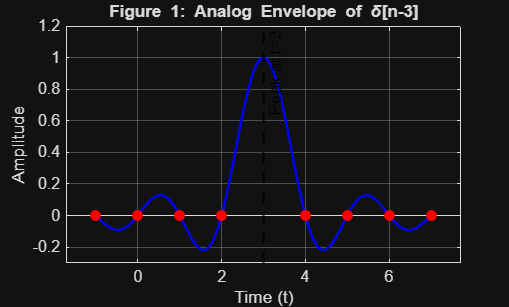

% 7.3 a)

% --- Figure 1: Analog Envelope of x[n] = delta[n-3] ---

% Define the sinc function centered at t=3
sinc_shifted = @(t) sin(pi*(t - 3)) ./ (pi*(t - 3));

% Define a fine time vector for the continuous plot
t_cont = -1:0.01:7; 
x_cont = sinc_shifted(t_cont);

% Plot the continuous envelope
figure(1);
plot(t_cont, x_cont, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Analog Envelope x(t)');
hold on;

% Mark the discrete sampling points (should be 0 everywhere except t=3)
n_samples = -1:7;
x_samples = sinc_shifted(n_samples);
stem(n_samples, x_samples, 'r', 'filled', 'MarkerSize', 6, 'DisplayName', 'Samples');
hold off;

% Aesthetics
title('Figure 1: Analog Envelope of \delta[n-3]');
xlabel('Time (t)');
ylabel('Amplitude');
xline(3, 'k--', 'LineWidth', 1.5, 'Label', 'Peak at t=3');
ylim([-0.3 1.2]);
grid on;

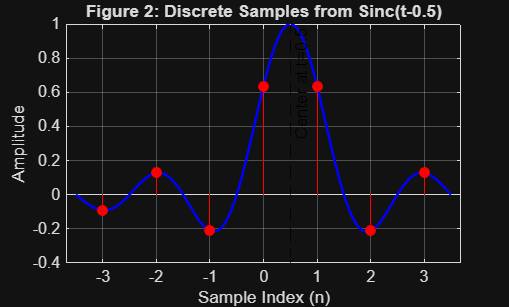


% 7.3 b)
% --- Figure 2: Discrete Signal from x(t) = sinc(t-0.5) ---

% Define the analog envelope centered at t=0.5
sinc_envelope = @(t) sin(pi*(t - 0.5)) ./ (pi*(t - 0.5));

% Define the range of the discrete signal
n = -3:3; 
x_n = sinc_envelope(n);

% 1. Plot the Analog Envelope for context
t_cont = -3.5:0.01:3.5; 
x_cont = sinc_envelope(t_cont);

figure(2);
plot(t_cont, x_cont, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Analog Envelope x(t)');
hold on;

% 2. Plot the Discrete Samples (Stem Plot)
stem(n, x_n, 'r', 'filled', 'MarkerSize', 6, 'DisplayName', 'Discrete Samples x[n]');
hold off;

% Aesthetics
title('Figure 2: Discrete Samples from Sinc(t-0.5)');
xlabel('Sample Index (n)');
ylabel('Amplitude');
xline(0.5, 'k--', 'Label', 'Center at t=0.5');
grid on;

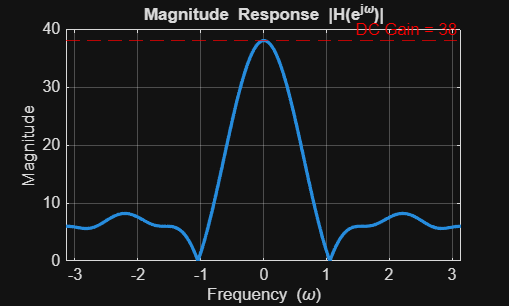

% 7.4b and d

% 1. Define the Impulse Response Coefficients
h = [2, 4, 6, 8, 6, 4, 8];

% 2. Compute the Frequency Response H(e^jw)
N_points = 512;
% freqz calculates H(e^jω) over the range [0, 2π] by default
[H, w_rad] = freqz(h, 1, N_points, 'whole');

% Shift the response and frequency vector to center at 0 (range [-π, π])
H_shifted = fftshift(H);
w_shifted = linspace(-pi, pi, N_points);

% --- Plotting the Magnitude Response |H(e^jω)| (Part 7.4b) ---
figure(1);
plot(w_shifted, abs(H_shifted), 'LineWidth', 2);
title('Magnitude Response |H(e^{j\omega})|');
xlabel('Frequency (\omega)');
ylabel('Magnitude');
xlim([-pi pi]);
% Mark the theoretical DC Gain (Sum of coefficients)
yline(sum(h), 'r--', 'Label', ['DC Gain = ', num2str(sum(h))]);
grid on;

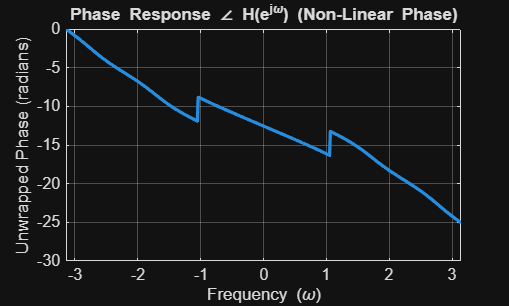


% --- Plotting the Phase Response ∠H(e^jω) (Part 7.4d) ---
figure(2);
% unwrap(angle(H_shifted)) calculates the continuous phase, showing non-linearity
plot(w_shifted, unwrap(angle(H_shifted)), 'LineWidth', 2);
title('Phase Response \angle H(e^{j\omega}) (Non-Linear Phase)');
xlabel('Frequency (\omega)');
ylabel('Unwrapped Phase (radians)');
xlim([-pi pi]);
grid on;